folder = "C:\Users\Garren\Documents\FYP\Code_and_excel_file\Ester Subset (LOOCV Results)"; %folder name for saving images. Change manually
multiplier = counter; %number of LOOCV procedures per set of conditions
start = 1;
for i = 1 : index/multiplier %intial guess
    
    Plot.Rank(i,1) = LOOCV.Rank((i-1)*multiplier+1);
    Plot.RMSE(i,1) = sqrt( sum( (LOOCV.Original( (i-1)*multiplier+1:i*multiplier ) - ...
        LOOCV.Itterations( (i-1)*multiplier+1:i*multiplier )).^2 ) /multiplier);
    Plot.MAD(i,1) = mean(abs( (LOOCV.Original( (i-1)*multiplier+1:i*multiplier ) - ...
        LOOCV.Itterations( (i-1)*multiplier+1:i*multiplier ) )./...
        LOOCV.Original( (i-1)*multiplier+1:i*multiplier ) * 100 ));
    Plot.Centering(i,1) = LOOCV.Centering((i-1)*multiplier+1);
    Plot.Initial(i,1) = LOOCV.Initial((i-1)*multiplier+1);
    Plot.Composition(i,1) = LOOCV.Composition((i-1)*multiplier+1);
end

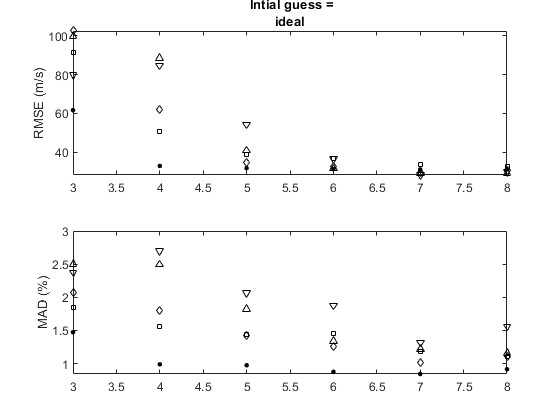

%plotting
formatting = [".k", "sk", "dk", "^k", "vk"]; %dot colours
msize = [10; 5; 5; 5; 5]; %markersize

counter = 0;
mm = 0; %counter
size_A = numel(unique(LOOCV.Rank));
for l=1:numel(unique(LOOCV.Initial)) %number of intial guess procedure
    
    for j = 1:numel(unique(LOOCV.Centering)) %number of centring procedures
        counter = counter + 1;
        for m = 1:5 %compositional slices
            mm = mm + 1;
            subplot(2, 1, 1);
            plot(Plot.Rank( (mm-1)*size_A+1:mm*size_A), Plot.RMSE( (mm-1)*size_A+1:mm*size_A), formatting(m), 'MarkerSize',msize(m));
            ylabel("RMSE (m/s)");
            hold on;
            subplot(2,1,2);
            plot(Plot.Rank( (mm-1)*size_A+1:mm*size_A), Plot.MAD( (mm-1)*size_A+1:mm*size_A), formatting(m), 'MarkerSize',msize(m));
            ylabel("MAD (%)")
            hold on;
            
            [Min_RMSE(counter,m) , Optimal_rank(counter, m)] = min(Plot.RMSE( (mm-1)*size_A+1:mm*size_A));
            Optimal_rank(counter, m) = Optimal_rank(counter, m)+min(unique(LOOCV.Rank))-1;
        end
        subplot(2, 1, 1); hold off; title(["Centering =", Plot.Centering( (mm-1)*size_A+1)," Intial guess =", Plot.Initial( (mm-1)*size_A+1)])
        subplot(2, 1, 2); hold off; %pause(5)
        %below code saves images
        filename = "Centering =" + Plot.Centering( (mm-1)*size_A+1) + ", Intial guess =" + Plot.Initial( (mm-1)*size_A+1) + ".jpg";
        f = getframe(gcf);
        %imwrite(f.cdata, fullfile(folder, filename));
    end
end

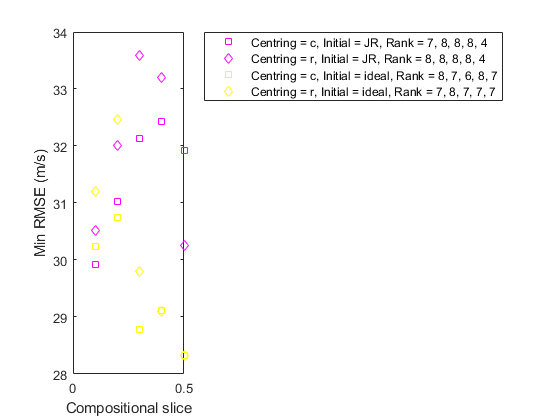

if numel(unique(LOOCV.Initial)) == 2
    formatting = ["sm", "dm", "sy", "dy"];
else
    formatting = ["sk", "dk", "sr", "dr", "sb", "db", "sg", "dg", "sm", "dm", "sy", "dy"]; 
end

Centring = unique(Plot.Centering, "stable");
Initial = unique(Plot.Initial, "stable");
counter = 0;
for i = 1:numel(unique(LOOCV.Initial)) %number of initial guesses
    for j = 1:numel(unique(LOOCV.Centering)) %number of centring procedures
        counter = counter+1;
        Centering_and_intial(counter) = "Centring = " + Centring(j) + ", Initial = " + Initial(i);
    end
end

for i = 1:size(Min_RMSE,1)
    subplot(1, 1, 1);
    plot((1:5)./10, Min_RMSE(i,:), formatting(i)); hold on
    legend_format(i,1) = Centering_and_intial(i) + ", Rank = " + Optimal_rank(i,1) + ", "+...
        Optimal_rank(i,2) + ", " + Optimal_rank(i,3) + ", " + Optimal_rank(i,4) + ", " +...
        Optimal_rank(i,5);
end
subplot(1,1,1); hold off; ylabel("Min RMSE (m/s)"); xlabel("Compositional slice");
filename = "Min RMSE.jpg";
f = getframe(gcf);
%imwrite(f.cdata, fullfile(folder, filename)); 
legend([legend_format], "Location","bestoutside")

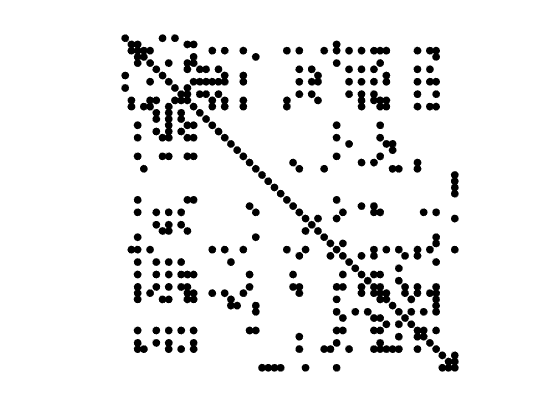

spy(tensor_4D(index_smaller_subset, index_smaller_subset, 1, 1), '.k', 20); axis off; %xlim([1 7]); ylim([1 7]);
filename = "Sparsity.jpg";
f = getframe(gcf);

%imwrite(f.cdata, fullfile(folder, filename)); 